# Actividad 1: Velocidades Lineales y angulares

## Objetivo

Para esta actividad se debe obtener el vector de velocidades lineal y angular para un robot de 3 grados de libertad (GDL):

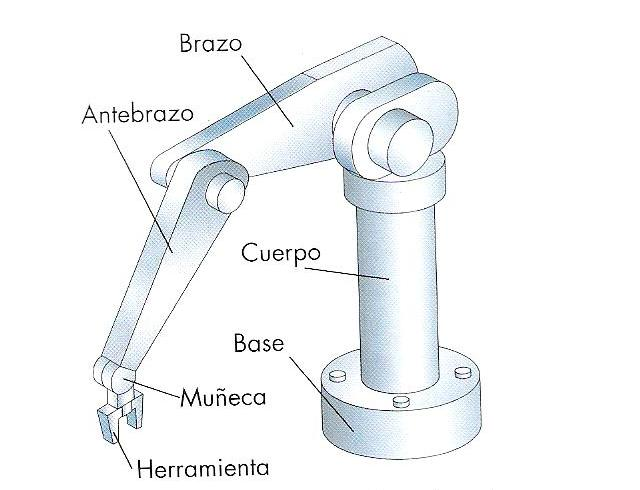

Imagen 1. Modelo.

### Procedimiento

Primero se limpia la pantalla y valores, para poder declarar las variables simbólicas, es decir, no tienen un valor en específico.

clear all
close all
clc

syms th1(t) a1 t  
syms th2(t) a2 
syms th3(t) a3

Posterioremente se hace la configuración del robot, 0 para junta rotacional, 1 para junta prismática, además de crear el vector de coordenadas articulares (Posicion). En este caso, como son 3 articulaciones se colocan 3 ceros.

RP=[0 0 0];
Q= [th1, th2, th3];
disp('Coordenadas articulares');

Coordenadas articulares


pretty (Q);

(th1(t), th2(t), th3(t))



Sacando la derivada del vector de coordenadas articulares con la función diff, obtenemos la velocidad articular.

Qp= diff(Q, t); %diff() para derivadas con variable de referencia que no depende de otra: ejemplo el tiempo
disp('Velocidades articulares');

Velocidades articulares


pretty (Qp);

/  d          d          d        \
| -- th1(t), -- th2(t), -- th3(t) |
\ dt         dt         dt        /



Con la función size se declara el número de grados de libertad que tiene el robot con el vector RP previamente definido, siempre se coloca 2, ya que indica la dimensión de las columnas y se convierte a string para posteriormente declarar el nombre a las matrices.

GDL= size(RP,2);
GDL_str= num2str(GDL);

Usando metodos trigonométricos declaramos la posción para la articulación 1 respecto a 0, como el brazo robótico tiene movimiento únicamente sobre el eje "x" y "y", por lo que es necesario analizar la posición que tendrá en cada instante de tiempo como se muestra en la siguiente imagen

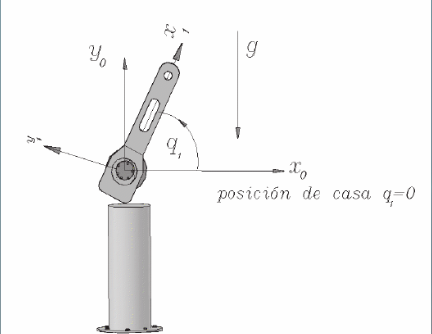

Imagen 2. Análisis trigonométrico

Este análisis se repite para cada una de las 3 articulaciones.

%Articulación 1 
%Se coloca en la página 1
P(:,:,1)= [a1*cos(th1);
           a1*sin(th1);
                    0];%Vector de posición indexado por página


También declaramos la matriz de rotación respecto a 0 obteniendo el análisis del robot péndulo, sieguiendo la matriz específica para el robot tipo péndulo.

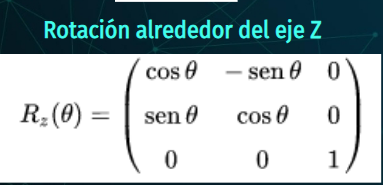

Imagen 3. Matriz de rotación al rededor del eje Z

%Matriz de rotación de la articulación 1 respecto a 0
R(:,:,1)= [cos(th1) -sin(th1)  0;
           sin(th1)  cos(th1)  0;
           0         0         1];

Repetimos el mismo procedimiento para las otras dos articulaciones, ya que tienen la misma configuración.

%Articulación 2 
%Posición de la junta 2 respecto a 0, se coloca en la página 2
P(:,:,2)= [a2*cos(th2);
           a2*sin(th2);
                     0];%Vector de posición indexado por página

%Matriz de rotación de la articulación 2 respecto a 0
R(:,:,2)= [cos(th2) -sin(th2)  0; 
           sin(th2)  cos(th2)  0;
           0         0         1];

%Articulación 3 
%Posición de la junta 3 respecto a 0, se coloca en la página 3
P(:,:,3)= [a3*cos(th3);
           a3*sin(th3);
                     0];%Vector de posición indexado por página

%Matriz de rotación de la articulación 3 respecto a 0
R(:,:,3)= [cos(th3) -sin(th3)  0;
           sin(th3)  cos(th3)  0;
           0         0         1];


Se crea el vector de ceros y se inicializa tanto las matrices de transformación homogénea locales como las matrices de transformación homogénea globales

Vector_Zeros= zeros(1, 3);

%Local
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Global
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

Se inicializan los vectores de posición vistos desde el marco de referencia inercial con el número de grados de libertad

PO(:,:,GDL)= P(:,:,GDL)

$$\left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

$$\left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

$$\left(\begin{array}{c} a_{3}\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right)\\ a_{3}\,\sin\left({\mathrm{th}}_{3}\left(t\right)\right)\\ 0 \end{array}\right)$$

Se Inicializan las matrices de rotación vistas desde el marco de referencia inercial con el número de grados de libertad

RO(:,:,GDL)= R(:,:,GDL)

$$\left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{3}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{3}\left(t\right)\right) & 0\\ \sin\left({\mathrm{th}}_{3}\left(t\right)\right) & \cos\left({\mathrm{th}}_{3}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Ahora en un ciclo for hará el procedimiento el número de veces de grados de libertad que tenga el robot. En este for se despliega las matrices de transformación locales y las globales, con un try catch se hace la excepción si el robot sólo cuenta con un grado de libertad. La mattriz global es la multiplicación de las locales.

for i = 1:GDL
    i_str= num2str(i);
    %Locales
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));

    %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);  %Caso específico cuando i=1 nos marcaría error en try
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i));
    %Obtenemos la matriz de rotación "RO "y el vector de translación PO de la
    %matriz de transformación Homogénea global T(:,:,GDL)
    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    pretty(RO(:,:,i));
    pretty(PO(:,:,i));
end

Matriz de Transformación local A1


/ cos(th1(t)), -sin(th1(t)), 0, a1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, a1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T1


/ cos(th1(t)), -sin(th1(t)), 0, a1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, a1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



/ cos(th1(t)), -sin(th1(t)), 0 \
|                              |
| sin(th1(t)),  cos(th1(t)), 0 |
|                              |
\      0,            0,      1 /



/ a1 cos(th1(t)) \
|                |
| a1 sin(th1(t)) |
|                |
\        0       /



Matriz de Transformación local A2


/ cos(th2(t)), -sin(th2(t)), 0, a2 cos(th2(t)) \
|                                              |
| sin(th2(t)),  cos(th2(t)), 0, a2 sin(th2(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T2


/ #2, -#1, 0, a1 cos(th1(t)) + a2 #2 \
|                                    |
| #1,  #2, 0, a1 sin(th1(t)) + a2 #1 |
|                                    |
|  0,  0,  1,            0           |
|                                    |
\  0,  0,  0,            1           /

where

   #1 == sin(th1(t) + th2(t))

   #2 == cos(th1(t) + th2(t))




/ cos(th1(t) + th2(t)), -sin(th1(t) + th2(t)), 0 \
|                                                |
| sin(th1(t) + th2(t)),  cos(th1(t) + th2(t)), 0 |
|                                                |
\           0,                    0,           1 /



/ a1 cos(th1(t)) + a2 cos(th1(t) + th2(t)) \
|                                          |
| a1 sin(th1(t)) + a2 sin(th1(t) + th2(t)) |
|                                          |
\                     0                    /



Matriz de Transformación local A3


/ cos(th3(t)), -sin(th3(t)), 0, a3 cos(th3(t)) \
|                                              |
| sin(th3(t)),  cos(th3(t)), 0, a3 sin(th3(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T3


/ #2, -#1, 0, a1 cos(th1(t)) + a3 #2 + a2 cos(th1(t) + th2(t)) \
|                                                              |
| #1,  #2, 0, a1 sin(th1(t)) + a3 #1 + a2 sin(th1(t) + th2(t)) |
|                                                              |
|  0,  0,  1,                         0                        |
|                                                              |
\  0,  0,  0,                         1                        /

where

   #1 == sin(th1(t) + th2(t) + th3(t))

   #2 == cos(th1(t) + th2(t) + th3(t))




/ cos(th1(t) + th2(t) + th3(t)), -sin(th1(t) + th2(t) + th3(t)), 0 \
|                                                                  |
| sin(th1(t) + th2(t) + th3(t)),  cos(th1(t) + th2(t) + th3(t)), 0 |
|                                                                  |
\               0,                              0,               1 /



/ a1 cos(th1(t)) + a3 cos(th1(t) + th2(t) + th3(t)) + a2 cos(th1(t) + th2(t)) \
|                                                                             |
| a1 sin(th1(t)) + a3 sin(th1(t) + th2(t) + th3(t)) + a2 sin(th1(t) + th2(t)) |
|                                                                             |
\                                      0                                      /



Ya con esto se calcula el jacobiano lineal de forma diferencial, para esta matriz se deriva parcialmente theta 1, theta 2 y theta 3, respecto a los ejes. Con las derivadas acomodamos los valores y creamos la matriz del jacobiano.

disp('Jacobiano lineal obtenido de forma diferencial');

Jacobiano lineal obtenido de forma diferencial


Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), th2);
Jv13= functionalDerivative(PO(1,1,GDL), th3);

Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), th2);
Jv23= functionalDerivative(PO(2,1,GDL), th3);

Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), th2);
Jv33= functionalDerivative(PO(3,1,GDL), th3);

%Reconstrucción de matriz
jv_d=simplify([Jv11 Jv12  Jv13;
              Jv21  Jv22  Jv23;
              Jv31  Jv32  Jv33]);

pretty(jv_d);

/ - a1 sin(th1(t)) - #1 - a2 sin(th1(t) + th2(t)), - #1 - a2 sin(th1(t) + th2(t)), -#1 \
|                                                                                      |
|  a1 cos(th1(t)) + #2 + a2 cos(th1(t) + th2(t)),   #2 + a2 cos(th1(t) + th2(t)),   #2 |
|                                                                                      |
\                        0,                                       0,                0  /

where

   #1 == a3 sin(th1(t) + th2(t) + th3(t))

   #2 == a3 cos(th1(t) + th2(t) + th3(t))




Ahora se realiza el cálculo del jacobiano lineal de forma analítica, para esto se inicializa los jacobianos analíticos (lineal y angular).

Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

Nuevamente se utiliza un ciclo para construir los jacobianos, con una condición haca el procedimiento para una articulación rotacional o prismática, si en RP es 0 significa que es rotacional y con 1 es prismática,  dentro de la condición hay try catch para los grados de libertad del robot.

Dependiendo del caso identificado, sea articulación rotacional o lineal, es la fórmula que se emplea.

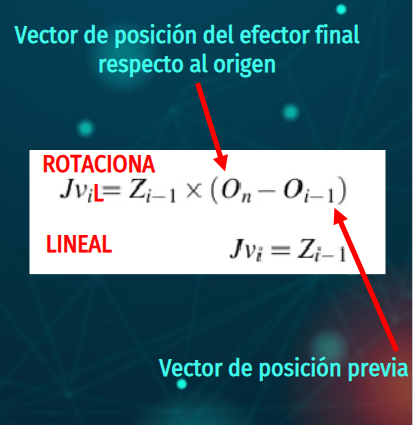

Fórmula 1.


for k= 1:GDL
    if ((RP(k)==0)||(RP(k)==1))%Casos: articulación rotacional y prismática

       %Para las articulaciones rotacionales
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));%producto cruz consultado de fórmula 1.
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL)); %Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
         %Para las articulaciones prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];%tercera columna de la matriz identidad
        end
            Jw_a(:,k)=[0,0,0];
     end
end    


#### Resultados

Para finalmente desplegar los resultados con simplify y pretty para tener una visualización más entendible.

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);

Resultado de las operaciones hechas en el ciclo for para obtener el jacobiano lineal.

disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ - a1 sin(th1(t)) - #1 - a2 sin(th1(t) + th2(t)), - #1 - a2 sin(th1(t) + th2(t)), -#1 \
|                                                                                      |
|  a1 cos(th1(t)) + #2 + a2 cos(th1(t) + th2(t)),   #2 + a2 cos(th1(t) + th2(t)),   #2 |
|                                                                                      |
\                        0,                                       0,                0  /

where

   #1 == a3 sin(th1(t) + th2(t) + th3(t))

   #2 == a3 cos(th1(t) + th2(t) + th3(t))




Resultado del jacobiano angular obtenido de la forma analítica muestra, en este jacobiano, por ser angular muestra que el eje que actúa es el z, y son tres columnas por ser de tres grados de libertad.

disp('Jacobiano ángular');

Jacobiano ángular


pretty (Jw_a);

/ 0, 0, 0 \
|         |
| 0, 0, 0 |
|         |
\ 1, 1, 1 /



Al observar la velocidad lineal podemos comprobar que es correcto, porque en el único eje que no hay velocidad lineal es sobre el eje Z, por lo tanto se muestra un cero.

disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/ - #4 (a3 sin(#1) + a2 sin(#2)) - #5 (a1 sin(th1(t)) + a3 sin(#1) + a2 sin(#2)) - a3 #3 sin(#1) \
|                                                                                                |
|  #4 (a3 cos(#1) + a2 cos(#2)) + #5 (a1 cos(th1(t)) + a3 cos(#1) + a2 cos(#2)) + a3 #3 cos(#1)  |
|                                                                                                |
\                                                0                                               /

where

   #1 == th1(t) + th2(t) + th3(t)

   #2 == th1(t) + th2(t)

         _________
          d
   #3 == -- th3(t)
         dt

         _________
          d
   #4 == -- th2(t)
         dt

         _________
          d
   #5 == -- th1(t)
         dt




Como podemos ver, efectivamente tenemos la diferencial en Z de theta 1, theta 2 y theta 3 en la valocidad angular, ya que es el único eje en el que actúa. Son tres articulaciones las que están unidas en el brazo robótico, por eso se están sumando.

disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/                 0                 \
|                                   |
|                 0                 |
|                                   |
| _________   _________   _________ |
|  d           d           d        |
| -- th1(t) + -- th2(t) + -- th3(t) |
\ dt          dt          dt        /

